## Data sampling for ID

### trim data

start_time = duration('00:02:16.148000');
end_time = duration('00:02:16.14850');

% Create a timerange object
ts_range = timerange(start_time, end_time);

% Index both pitch_in and elevator using the rows subscript
elevator_trim = pitch_in.pitch_in(ts_range,:) - elevator.elevator(ts_range,:)

elevator_trim = 0.1368

throttle_trim = throttle_in.throttle_in(ts_range,:) - throttle.throttle(ts_range,:)

throttle_trim = 0.3304

airspeed_trim = ind_airspeed.indicated_airspeed(ts_range,:)

airspeed_trim = single
14.7282

alt_trim = alt.alt(ts_range,:)

alt_trim = single
235.1120

pitch_rate_trim = q.q(ts_range,:)

pitch_rate_trim = 0.7505

alpha_trim = alpha.alpha(ts_range,:)

alpha_trim = single
0.9369

### step input

t_start = duration('00:01:57.223879');
t_end_s = duration('00:02:05.233258');
t_end_p = duration('00:02:15.379288');

% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_step = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_step = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_step = q.q(ts_range,:); 
aoa_s_step = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_step = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_step = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_step = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_step = alt.alt(ts_range,:);

### doublet input

t_start = duration('00:03:00.829399');
t_end_s = duration('00:03:05.306886');
t_end_p = duration('00:03:11.179269');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_doublet = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_doublet = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_doublet = q.q(ts_range,:); 
aoa_s_doublet = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_doublet = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_doublet = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_doublet = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_doublet = alt.alt(ts_range,:);

### sine sweep input

t_start = duration('00:03:38.946086');
t_end_s = duration('00:03:59.769274');
t_end_p = duration('00:03:59.769274');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_sine = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_sine = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_sine = q.q(ts_range,:); 
aoa_s_sine = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_sine = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_sine = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_sine = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_sine = alt.alt(ts_range,:);

## System ID script - step

iodelay = 0;
u1 = throttle_s_step;
u2 = elevator_s_step;
u3 = throttle_p_step;
u4 = elevator_p_step;
airspeed_trim = vel_p_step(1,1);
alt_trim = alt_p_step(1,1);
pitch_rate_trim = q_s_step(1,1);
alpha_trim = aoa_s_step(1,1);
y3 = q_s_step - pitch_rate_trim;
y1 = double(vel_p_step - airspeed_trim);
y4 = double(aoa_s_step - alpha_trim);
y5 = double(alt_p_step - alt_trim);

### MIMO identification - short period mode

u = [u1];
y = [y3];
np = [2];%[2 2; 2 2];
nz = [1]%[1 2; 1 1];

nz = 1

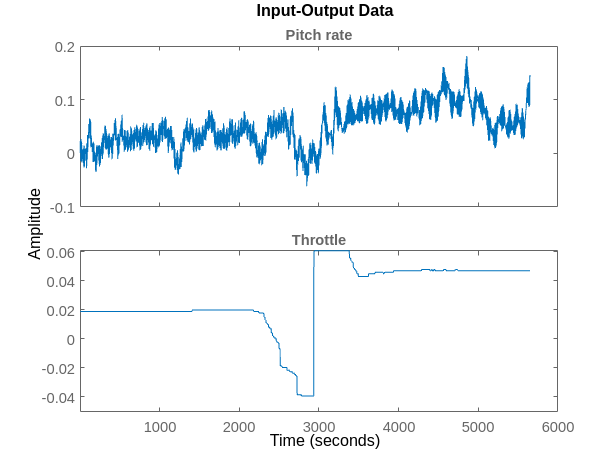

data = iddata(y,u);
set(data,'InputName',{'Throttle'},'OutputName',{'Pitch rate'})
plot(data)

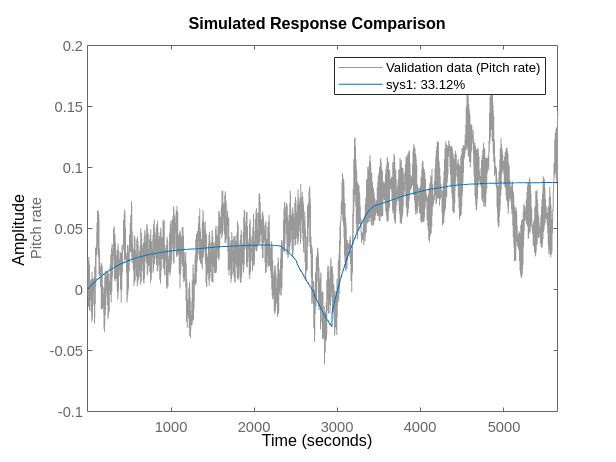

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

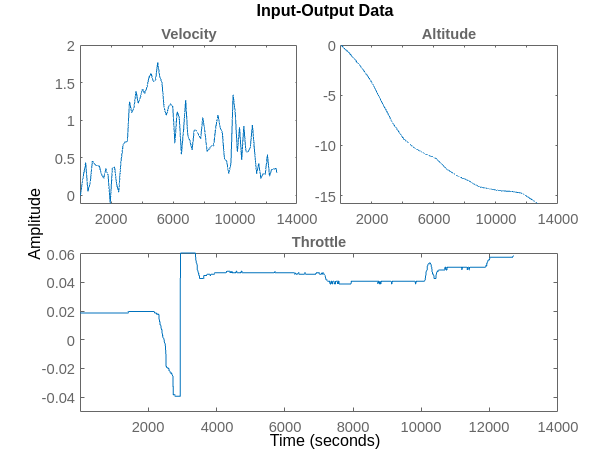

u = [u3];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u);
set(data,'InputName',{'Throttle'},'OutputName',{'Velocity', 'Altitude'}); %,'Evelator deflection'
plot(data)

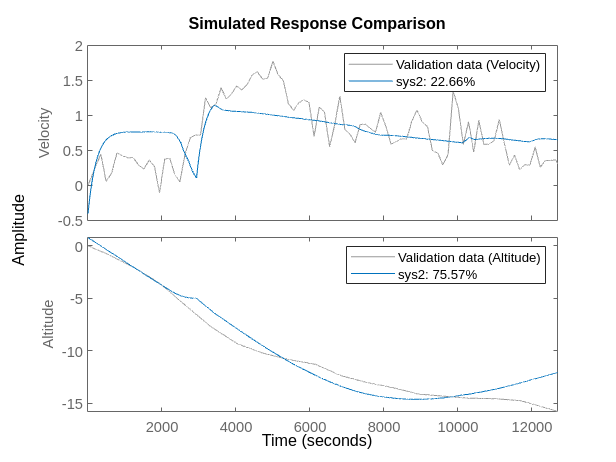

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

G1_tf = tf([sys1; sys2])  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G1_tf =
 
  From input "Throttle" to output...
                  0.5404 s + 0.01938
   Pitch rate:  -----------------------
                s^2 + 4.598 s + 0.01035
 
                 0.06014 s - 6.211e-06
   Velocity:  ----------------------------
              s^2 + 0.004407 s + 2.317e-15
 
                 -0.02705 s - 9.406e-06
   Altitude:  -----------------------------
              s^2 + 5.816e-05 s + 6.512e-08
 
Continuous-time transfer function.



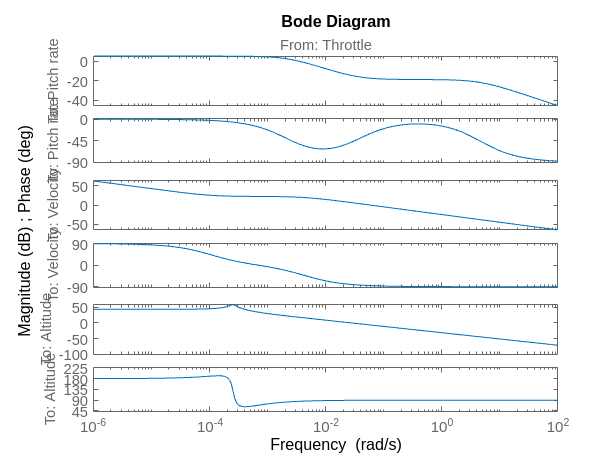

bode(G1_tf)

## System ID script - doublet

iodelay = 0;
u1 = throttle_s_doublet-0.0533;
u2 = elevator_s_doublet;
u3 = throttle_p_doublet-0.0533;
u4 = elevator_p_doublet;
airspeed_trim = vel_p_doublet(1,1);
alt_trim = alt_p_doublet(1,1);
pitch_rate_trim = q_s_doublet(1,1);
alpha_trim = aoa_s_doublet(1,1);
y1 = double(vel_p_doublet - airspeed_trim);
y3 = q_s_doublet - pitch_rate_trim;
y4 = double(aoa_s_doublet - alpha_trim);
y5 = double(alt_p_doublet - alt_trim);

### MIMO identification - short period mode

u = [u1];
y = [y3];
np = [2];%[2 2; 2 2];
nz = [1]%[1 2; 1 1];

nz = 1

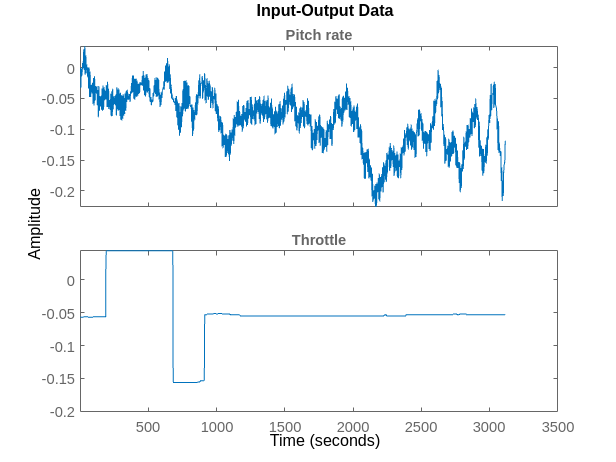

data = iddata(y,u);
set(data,'InputName',{'Throttle'},'OutputName',{'Pitch rate'})
plot(data)

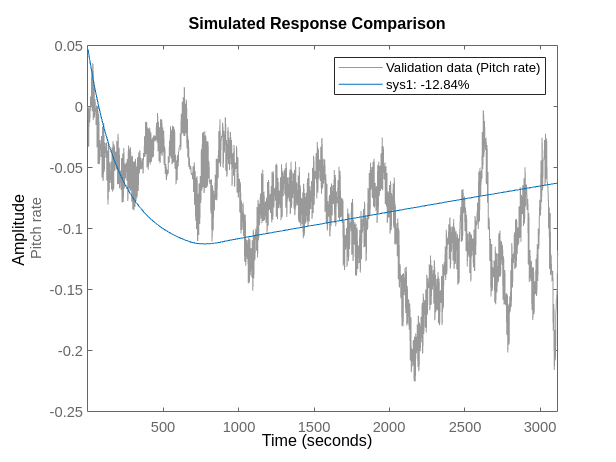

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

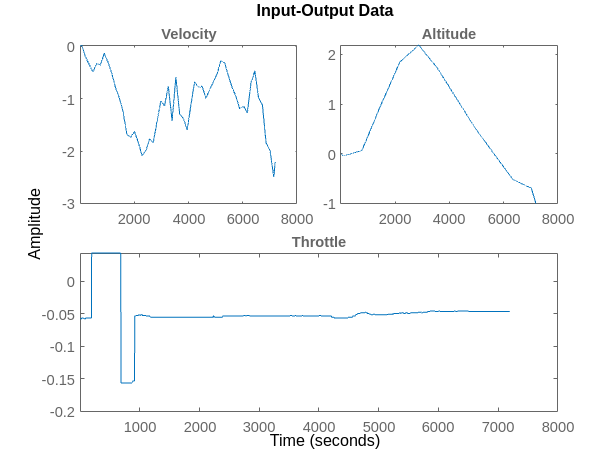

u = [u3];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u);
set(data,'InputName',{'Throttle'},'OutputName',{'Velocity', 'Altitude'});
plot(data)

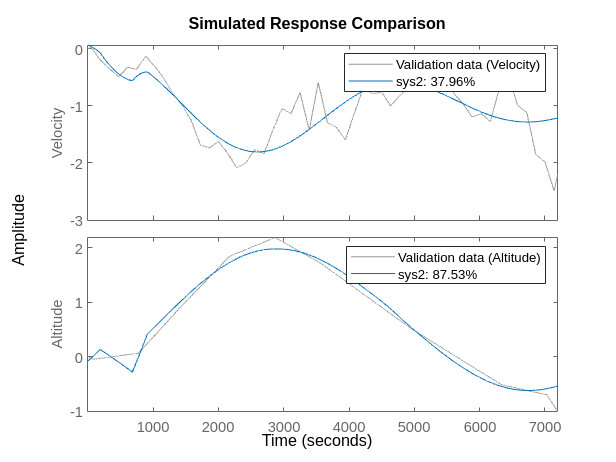

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

G2_tf = tf([sys1; sys2])  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G2_tf =
 
  From input "Throttle" to output...
                  -4.403e-05 s - 1.888e-06
   Pitch rate:  ----------------------------
                s^2 + 0.004826 s + 5.048e-14
 
                 -0.007997 s + 4.385e-05
   Velocity:  -----------------------------
              s^2 + 0.0002983 s + 2.129e-06
 
                 -0.01893 s - 8.817e-06
   Altitude:  -----------------------------
              s^2 + 0.0001017 s + 7.096e-07
 
Continuous-time transfer function.



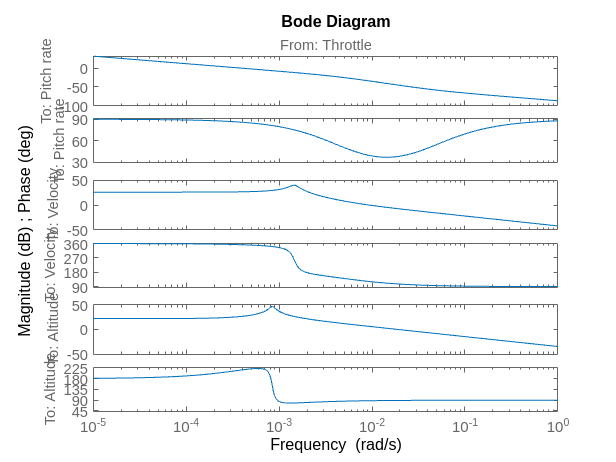

bode(G2_tf)

## System ID script - sine sweep

iodelay = 0;
u1 = throttle_s_sine-0.0533;
u2 = elevator_s_sine;
u3 = throttle_p_sine-0.0533;
u4 = elevator_p_sine;
airspeed_trim = vel_p_sine(1,1);
alt_trim = alt_p_sine(1,1);
pitch_rate_trim = q_s_sine(1,1);
alpha_trim = aoa_s_sine(1,1);
y1 = double(vel_p_sine - airspeed_trim);
y3 = q_s_sine - pitch_rate_trim;
y4 = double(aoa_s_sine - alpha_trim);
y5 = double(alt_p_sine - alt_trim);

### MIMO identification - short period mode

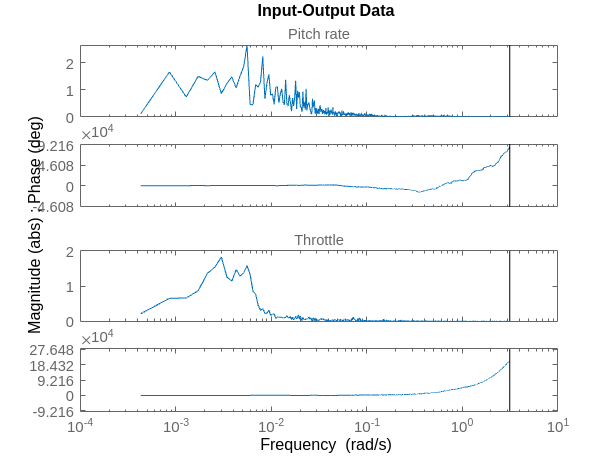

u = [u1];
y = [y3];
np = [2];%[2 2; 2 2];
nz = [1];%[1 2; 1 1];
data = iddata(y,u);
data = fft(data);
set(data,'InputName',{'Throttle'},'OutputName',{'Pitch rate'})
plot(data)

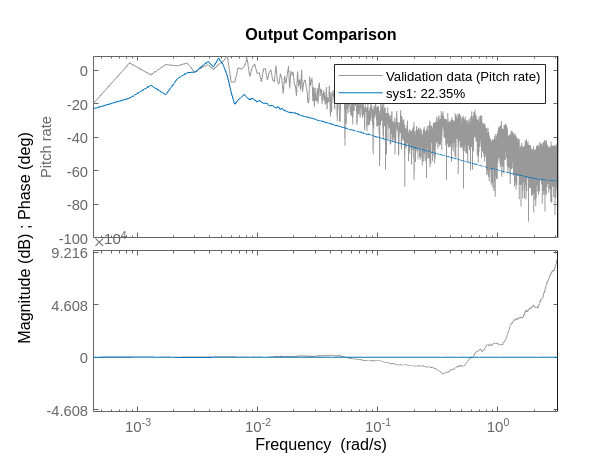

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

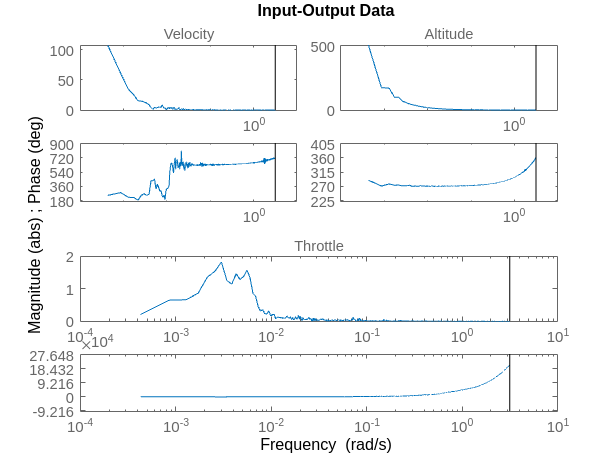

u = [u3];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u);
data = fft(data);
set(data,'InputName',{'Throttle'},'OutputName',{'Velocity', 'Altitude'})
plot(data)

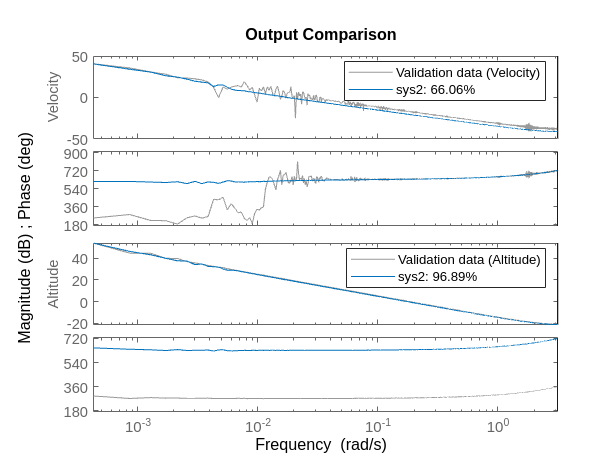

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

G3_tf = tf([sys1; sys2]) %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G3_tf =
 
  From input "Throttle" to output...
                   0.0004761 s - 5.418e-06
   Pitch rate:  -----------------------------
                s^2 + 0.0007528 s + 1.849e-05
 
                -0.00401 s + 6.566e-06
   Velocity:  ---------------------------
              s^2 + 0.00186 s - 1.624e-07
 
                  0.01103 s + 9.791e-06
   Altitude:  -----------------------------
              s^2 + 0.0002023 s + 6.246e-08
 
Continuous-time transfer function.



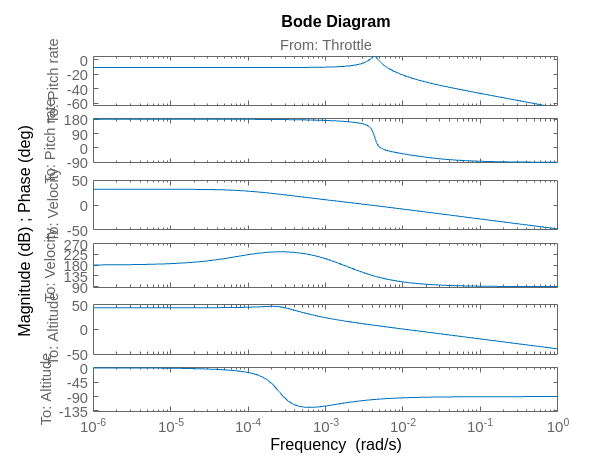

bode(G3_tf)